# Proyecto Pendulo

Andrea de Anda Kuri

173347

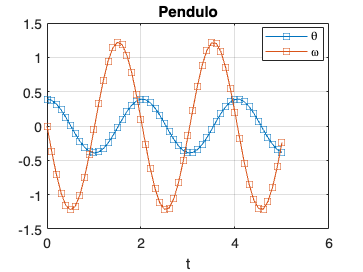

y0=[pi/8;0];
g=9.81;
l=1;
f=@(t,y) [y(2);-(g/l)*sin(y(1))];

t0=0;
tf=5;
h=0.1;
[t,y]=odeRK4bis(f,y0,t0,tf,h);

plot(t,y,'-s')
xlabel('t')
legend('\theta','\omega','location','best')
title('Pendulo')
grid on

function [t,y] =odeRK4bis(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end